# **Generating Random Number**

**1. (a) Using the LGM method generate 10,000 Uniformly distributed random numbers on [0,1] and compute the empirical mean and the standard deviation of the sequence.  **

% LGM method
% X_(n+1) = (aX_n + b) moudulo m
% where a = 2^16 + 3, b = 0, m=2^31-1
m = pow2(31)-1;
a = power(7,5)+3;
X_vector = 1:10000;
for i = 1:10000
    if i == 1
        % use 1 as X_0
        X_vector(i) = mod(a*1,m);
    else
        % generate next X based on current X
        X_vector(i) = mod(a*X_vector(i-1),m);
    end
end

% divide X by m to generate Uniformly distributed random numbers on [0,1]
U_vector = X_vector/m;
% get the standard deviation of the random numbers
U_std = std(U_vector);
% get the mean of the random numbers
U_mean = mean(U_vector);
% print the mean
fprintf('the empirical mean is %.4f\n', U_mean); 

the empirical mean is 0.4962


% print the standard deviation
fprintf('the standard deviation is %.4f\n', U_std); 

the standard deviation is 0.2897


**(b). Use built-in functions of the software you are using to do the same thing as in (a).  **

% generate 10,000 Uniformly distributed random numbers on [0,1] with
% built-in function
rng(100) % set seed for randomness
built_in_vector = rand([1 10000]);
% get the standard deviation of the random numbers
bi_std = std(built_in_vector);
% get the mean of the random numbers
bi_mean = mean(built_in_vector);
% print the mean
fprintf('the empirical mean is %.4f\n', bi_mean); 

the empirical mean is 0.4977


% print the standard deviation
fprintf('the standard deviation is %.4f\n', bi_std);

the standard deviation is 0.2891


**(c). Compare your findings in (a) and (b) and comment (be short, but precise). **

the mean and the standard deviation of (a) and (b) are similar.

**2. Use the numbers of part (a) of question 1 to do the following:**


$$  X =
    \begin{cases}
      -1 & \text{ with probability 0.3}\\
      0 & \text{with probability 0.35}\\
      1 & \text{with probability 0.2}\\
      2 & \text{with probability 0.15}\\
    \end{cases}$$


**(a) Generate 10,000 random numbers with the distribution**

% generate Bernoulli distributed numbers based on uniformly distributed numbers 
vector2 = U_vector;
% get the index of values less than 0.3
idx_neg1 = vector2 < 0.3;
% get the index of values between 0.3 and 0.65
idx_0 = (vector2 >= 0.3) & (vector2 < 0.65);
% get the index of values between 0.65 and 0.85
idx_1 = (vector2 >= 0.65) & (vector2 < 0.85);
% get the index of values no less than 0.85
idx_2 = vector2 >= 0.85;
% replace values less than 0.3 as -1
vector2(idx_neg1) = -1;
% replace values between 0.3 and 0.65 as 0
vector2(idx_0) = 0;
% replace values between 0.65 and 0.85 as 1
vector2(idx_1) = 1;
% replace values no less than 0.85 as 2
vector2(idx_2) = 2;

(b) Draw the histogram and compute the empirical mean and standard deviation of the sequence of 10,000 numbers generated in part (a).  

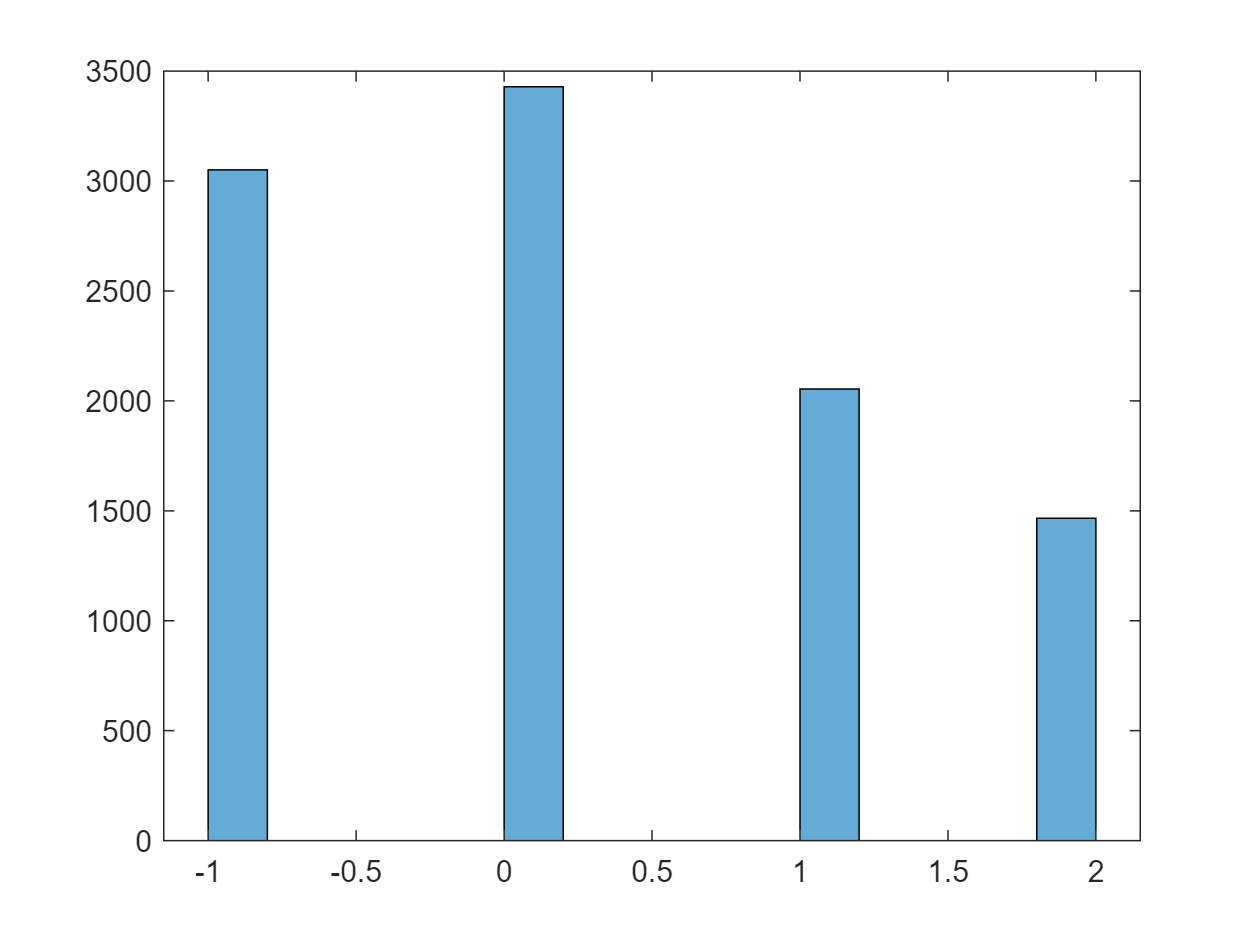

% draw histogram
nbins = 15; % number of bins
histogram(vector2,nbins)

% get the standard deviation of the random numbers
vector2_std = std(vector2);
% get the mean of the random numbers
vector2_mean = mean(vector2);
% print the mean
fprintf('the empirical mean is %.4f\n', vector2_mean); 

the empirical mean is 0.1935


% print the standard deviation
fprintf('the standard deviation is %.4f\n', vector2_std); 

the standard deviation is 1.0294


**3. Using the LGM method generate Uniformly distributed random numbers on [0,1] to do the following:  **

**(a) Generate 1,000 random numbers with Binomial distribution with n = 44 and p = 0.64.**

**(*****Hint*****: A random variable with Binomial distribution (n, p) is a sum of n Bernoulli (p) distributed random variables, so you will need to generate 44,000 Uniformly distributed random numbers, to start with).**

n = 44;
p = 0.64;
% generate Uniformly Distributed data
U_vector2 = generate_U(n*1000);
% store Binomial distributed numbers into Bin_vector
Bin_vector = 1:1000;

for i =1:1000
    % generate Bernoulli Distributed random numbers
    Bern_vector = generate_Bern(p, U_vector2(44*i-43:44*i));
    % Y1+Y2+...+Yn where Yi ~ Bern(p)
    Bin_vector(i) = sum(Bern_vector);
end

**(b) Draw the histogram. Compute the probability that the random variable X that has Binomial (44, 0.64) distribution, is at least 40: P(X ≥ 40). Use any statistics textbook or online resources for the exact number for the above probability and compare it with your finding and comment**

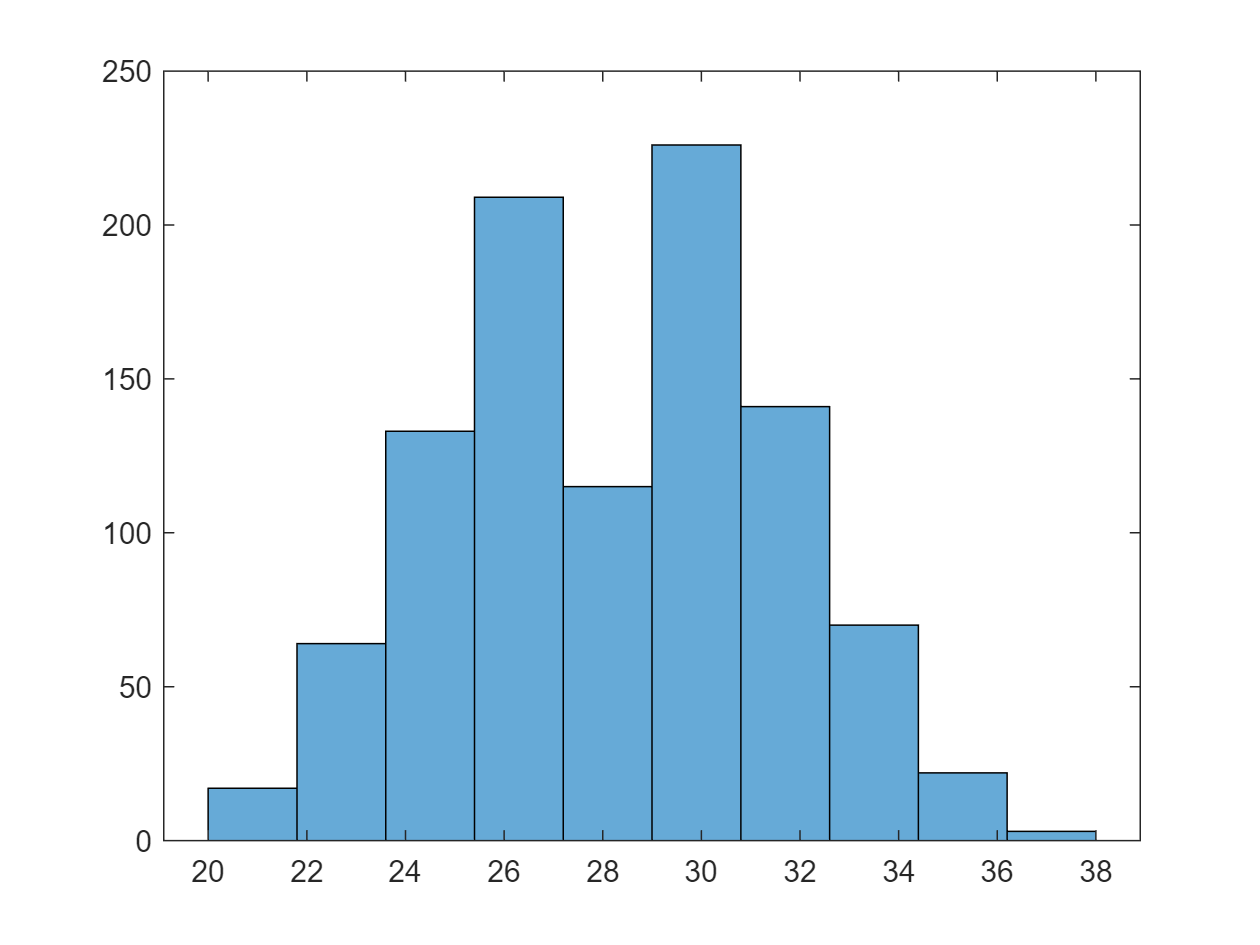

% draw histogram
nbins2 = 10; % number of bins
histogram(Bin_vector, nbins2)

P(x$\ge$40) = $C_{44}^{40}p^{40}(1-p)^4+C_{44}^{41}p^{41}(1-p)^3+C_{44}^{42}p^{42}(1-p)^2+C_{44}^{43}p^{43}(1-p)^1+C_{44}^{44}p^{44}$

% calculate the probability in theory
prob = 0;
for i = 40:44
    % 44 choose i x p^i x (1-p)^(44-i)
    prob = prob + nchoosek(44,i)*power(p,i)*power(1-p,44-i);
end

% print P(x>=40) value in theory
fprintf('the probability of X no less than 40 in theory is %.5f\n', prob); 

the probability of X no less than 40 in theory is 0.00005


% P(X >= 40)
prob_lt40 = sum(Bin_vector >= 40)/n;
% print P(x>=40) value in simulation
fprintf('the probability of X no less than 40 in simulation is %.5f\n', prob_lt40); 

the probability of X no less than 40 in simulation is 0.00000


Comments: These values from the theory and simulation are pretty close.

**4. Using the LGM method generate Uniformly distributed random numbers on [0,1] to:**

**(a) Generate 10,000 Exponentially distributed random numbers with parameter **$\lambda$** = 1.5  **

% set lambda = 1.5
lambda = 1.5;
% generate uniformly distributed data
E_vector = generate_U(10000);
% generate exponentially distributed numbers with lambda=1.5
E_vector = - log(1-E_vector) / lambda;

(b) Compute P(X≥ 1) and P(X ≥ 4).  

P(X$\ge$1)=$e^{-\lambda } =e^{-1\ldotp 5} =0\ldotp 22313$

P(X$\ge$4)=$e^{-4\lambda }$$=e^{-6} =0\ldotp 002479$

(c) Compute the empirical mean and the standard deviation of the sequence of 10,000 numbers generated in part (a). Draw the histogram by using the 10,000 numbers of part (a).  

% get the standard deviation of the random numbers
E_std = std(E_vector);
% get the mean of the random numbers
E_mean = mean(E_vector);
% print the mean of the random numbers
fprintf('the empirical mean is %.4f\n', E_mean); 

the empirical mean is 0.6572


% print the standard deviation of the random numbers
fprintf('the standard deviation is %.4f\n', E_std); 

the standard deviation is 0.6551


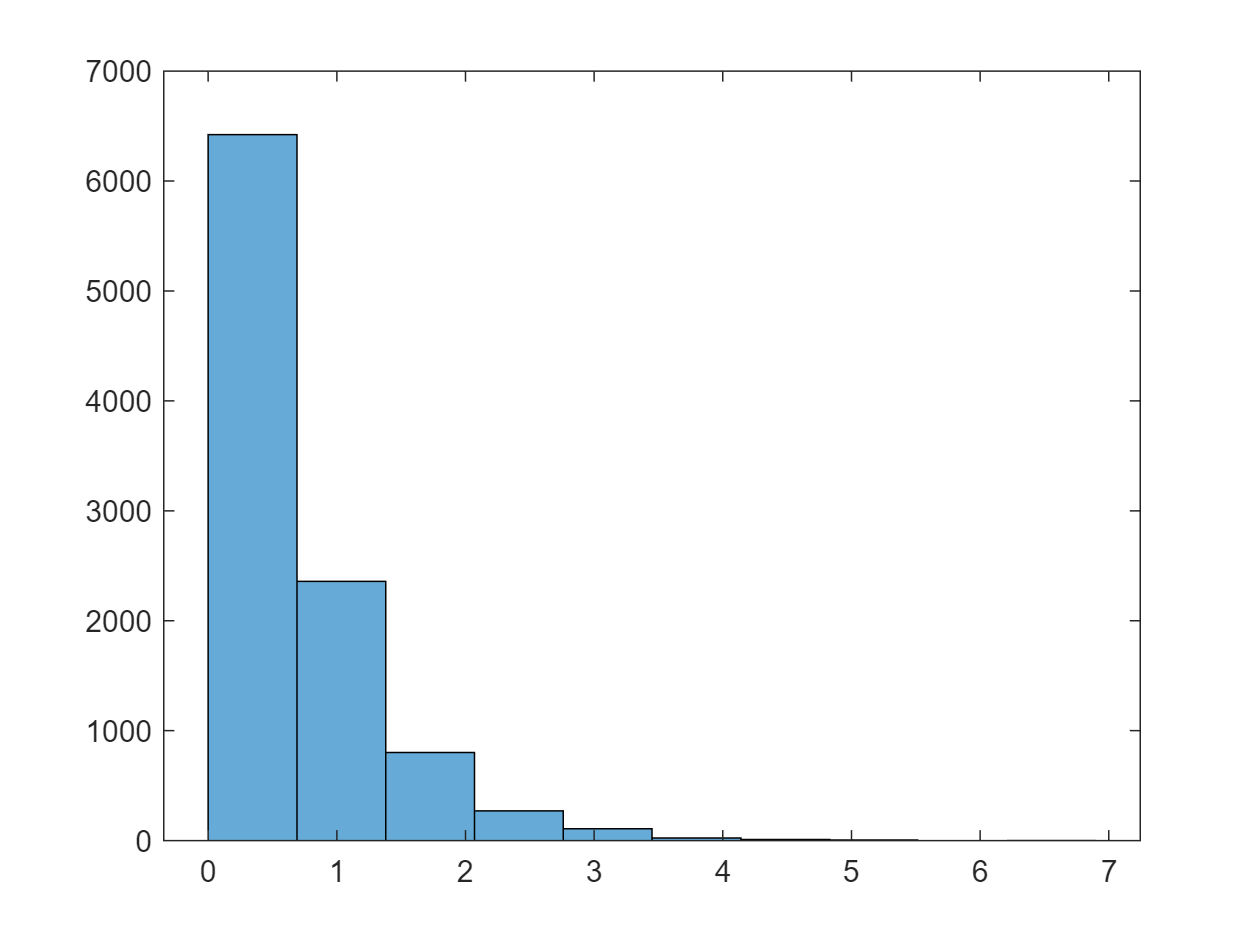

% draw histogram
nbins3=10; % number of bins
histogram(E_vector,nbins3)

**5. Using the LGM method generate Uniformly distributed random numbers on [0,1] to:  **

**(a) Generate 5,000 Normally distributed random numbers with mean 0 and variance 1, by BoxMuller Method.**

tic % begin to count executaion time
N=2500; % half of the number

% generate 2 sequences of 5000 normally distributed numbers
% using BoxMuller method
BM_vector1 = 1:N;
BM_vector2 = 1:N;
% generate 2 sequences of 5000 uniformly distributed numbers
m = pow2(31)-1;
a = power(7,5)+3;
X1 = 1; % initial X for series 1
X2 = 2*N+1; % initial X for series 2
i = 1;
while i <N+1
    % generate next X based on current X
    X1 = mod(a*X1,m);
    X2 = mod(a*X2,m);
    % generate U
    U1 = (X1+0.5)/m;
    U2 = (X2+0.5)/m;
    % generate Z1 and Z2
    BM_vector1(i) = sqrt(-2*log(U1))*cos(2*pi*U2);
    BM_vector2(i) = sqrt(-2*log(U1))*sin(2*pi*U2);
    i = i + 1;% increase the counter for the normally distributed pairs 
end
toc % end to count executaion time

Elapsed time is 0.008076 seconds.


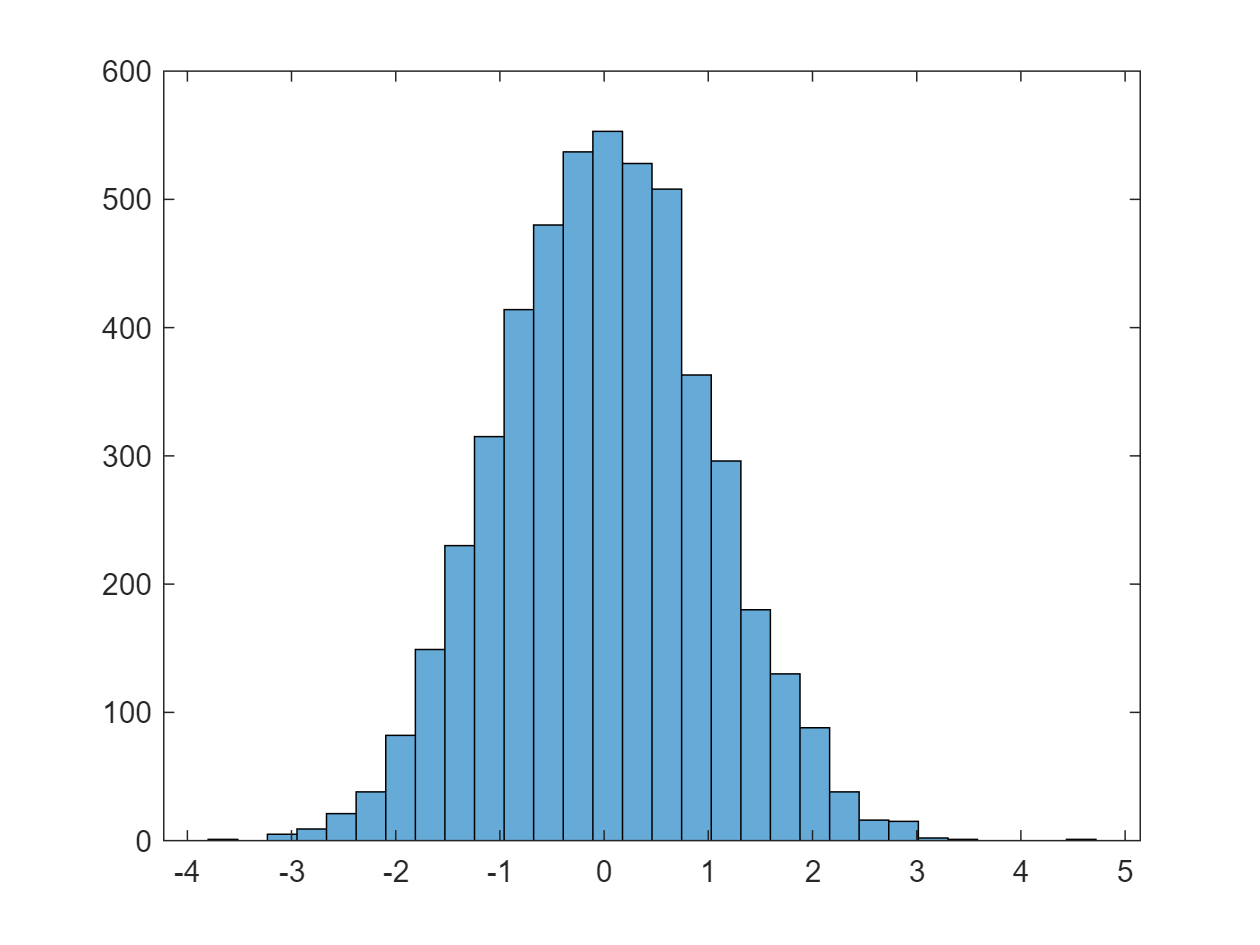

BM_vector = [BM_vector1, BM_vector2]; % combine two vectors
histogram(BM_vector,30) % plot the histogram

**(b) Now use the Polar-Marsaglia method to Generate 5,000 Normally distributed random numbers with mean 0 and variance 1.**

tic % begin to count executaion time
% generate 2 sequences of 5000 normally distributed numbers
% using Polar-Marshaglia method
N=2500; % half of the number
% initial vectors for Z1 and Z2 under Polar-Marsaglia method
PM_vector1 = 1:N;
PM_vector2 = 1:N;
% generate 2 sequences of 5000 uniformly distributed numbers
m = pow2(31)-1;
a = power(7,5)+3;
X1 = 1; % initial X for series 1
X2 = 2*N+1; % initial X for series 2
i=1;
while i < N+1
    % stop when there are already 5000 nomally distributed pairs generated
    % generate next X based on current X
    X1 = mod(a*X1,m);
    X2 = mod(a*X2,m);
    % generate U
    U1 = (X1+0.5)/m;
    U2 = (X2+0.5)/m;
    % generate V
    V1 = 2*U1 - 1;
    V2 = 2*U2 - 1;
    % compute W
    W = V1*V1 + V2*V2;
    if W <= 1
        % generate Z1 and Z2
        PM_vector1(i) = V1*sqrt(-2*log(W)/W);
        PM_vector2(i) = V2*sqrt(-2*log(W)/W);
        i = i + 1; % increase the counter for the normally distributed pairs 
    end
end

toc % end to count executaion time

Elapsed time is 0.009823 seconds.


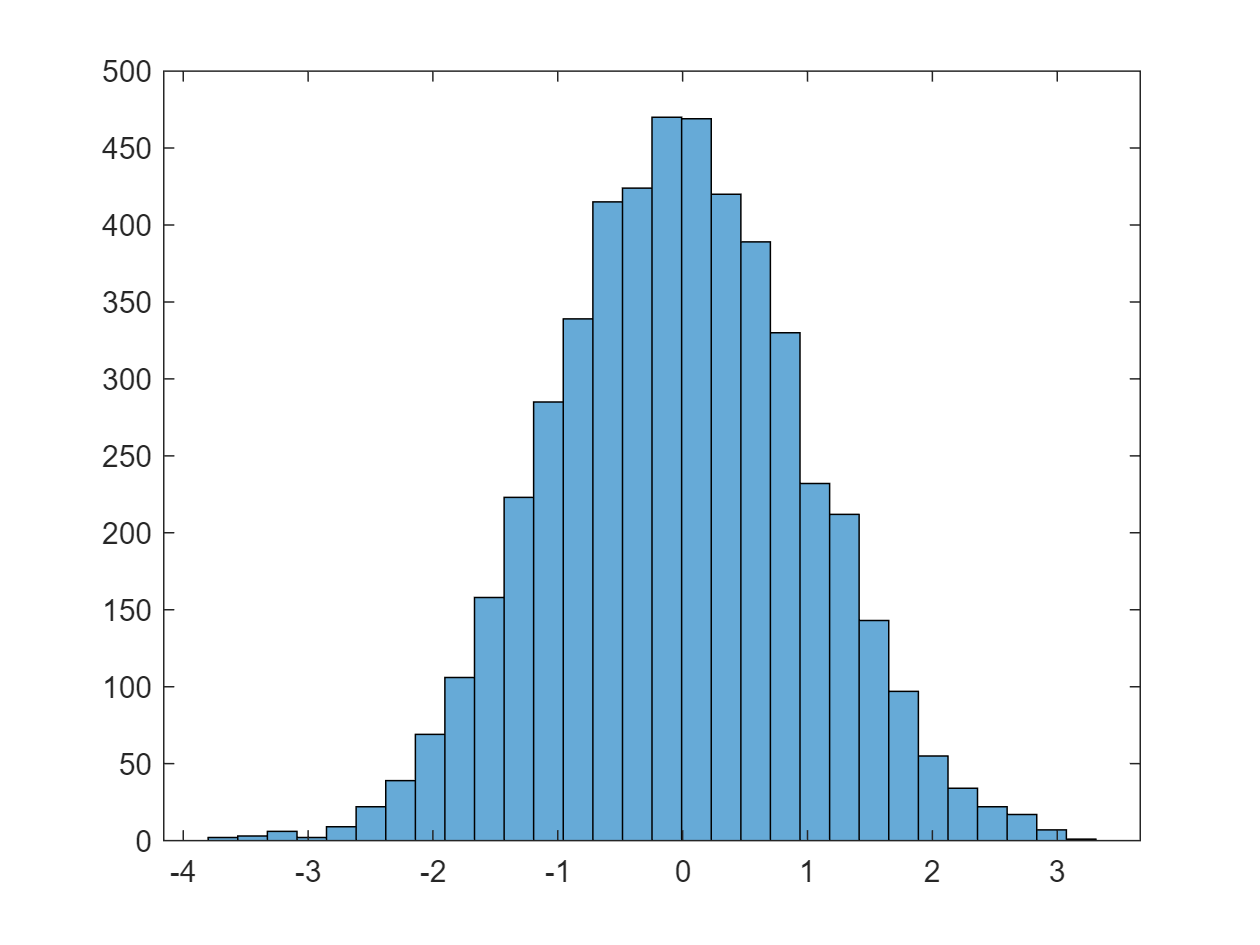

PM_vector = [PM_vector1, PM_vector2]; % combine two vectors
histogram(PM_vector,30) % plot the histogram

(c) Now compare the efficiencies of the two above-algorithms, by comparing the execution **times **to generate 5,000 normally distributed random numbers by the two methods. Which one is more efficient? If you do not see a clear difference, you need to increase the number of generated realizations of random variables to 10,000, 20,000, etc.

tic % begin to count executaion time
for try_time = 1:100
    N=2500; % half of the number
    
    % generate 2 sequences of 5000 normally distributed numbers
    % using BoxMuller method
    BM_vector1 = 1:N;
    BM_vector2 = 1:N;
    % generate 2 sequences of 5000 uniformly distributed numbers
    m = pow2(31)-1;
    a = power(7,5)+3;
    X1 = 1; % initial X for series 1
    X2 = 2*N+1; % initial X for series 2
    i = 1;
    while i <N+1
        % generate next X based on current X
        X1 = mod(a*X1,m);
        X2 = mod(a*X2,m);
        % generate U
        U1 = (X1+0.5)/m;
        U2 = (X2+0.5)/m;
        % generate Z1 and Z2
        BM_vector1(i) = sqrt(-2*log(U1))*cos(2*pi*U2);
        BM_vector2(i) = sqrt(-2*log(U1))*sin(2*pi*U2);
        i = i + 1;% increase the counter for the normally distributed pairs 
    end
end
toc % end to count executaion time

Elapsed time is 0.051543 seconds.


tic % begin to count executaion time
% generate 2 sequences of 5000 normally distributed numbers
% using Polar-Marshaglia method
for try_time = 1:100
    % generate 2 sequences of 5000 normally distributed numbers
    % using Polar-Marshaglia method
    N=2500; % half of the number
    % initial vectors for Z1 and Z2 under Polar-Marsaglia method
    PM_vector1 = 1:N;
    PM_vector2 = 1:N;
    % generate 2 sequences of 5000 uniformly distributed numbers
    m = pow2(31)-1;
    a = power(7,5)+3;
    X1 = 1; % initial X for series 1
    X2 = 2*N+1; % initial X for series 2
    i=1;
    while i < N+1
        % stop when there are already 5000 nomally distributed pairs generated
        % generate next X based on current X
        X1 = mod(a*X1,m);
        X2 = mod(a*X2,m);
        % generate U
        U1 = (X1+0.5)/m;
        U2 = (X2+0.5)/m;
        % generate V
        V1 = 2*U1 - 1;
        V2 = 2*U2 - 1;
        % compute W
        W = V1*V1 + V2*V2;
        if W <= 1
            % generate Z1 and Z2
            PM_vector1(i) = V1*sqrt(-2*log(W)/W);
            PM_vector2(i) = V2*sqrt(-2*log(W)/W);
            i = i + 1; % increase the counter for the normally distributed pairs 
        end
    end
end
toc % end to count executaion time

Elapsed time is 0.054182 seconds.


Since the executaion time is different for each time running time in matlab, I run them both for 100 times. So the total time can repsent the avaerage level. By running the process 100 times, we get their total time as shown above. Compared with Polar-Marsaglia method, BoxMuller method has less execuation time since Polar-Marsaglia method doesn't use the the parts of w larger than 1. So, BoxMuller method is more efficient in Matlab.

However, in Python, the execuation time of Polar-Marsaglia method is shorter than BoxMuller method, which is consistant with the conclusion of research paper. But the exectuation time in Matlab is not consistant with the conclustion of research paper. I guess there might be some programming design problem here (the different design logic of Matlab and Python).

**Functions used in this file**

function U_vector = generate_U(num) 
% generate num uniformly distributed numbers in [0,1] 
    m = pow2(31)-1;
    a = power(7,5)+3;
    X_vector = 1:num;
    for i = 1:num
        if i == 1
            % use 1 as X_0
            X_vector(i) = mod(a*1,m);
        else
            % generate next X based on current X
            X_vector(i) = mod(a*X_vector(i-1),m);
        end
    end
    % divide X by m
    U_vector = X_vector/m;
end

function Bern_vector = generate_Bern(p, U_vector)
% generate num Bernoulli(p) distributed numbers using a uniformally ditributed
% series in [0,1]
    Bern_vector = U_vector;
    % get the index of values less than p
    idx_lt = Bern_vector < p;
    % replace values less than p as 1
    Bern_vector(idx_lt) = 1;
    % replace values no less than p as 0
    Bern_vector(~idx_lt) = 0;
end